### Transfer Function

Recordar que la función de transferencia del sistema es:


$$\frac{V_c(s)}{V_{in}(s)} = \frac{1}{1 + RCs}$$


El tiempo de establecimiento viene dado por la constante $\tau = RC$, es decir, a más pequeño este producto más rápido llegamos al *setpoint.*

R =10000;
C = 470*1e-6;
H = tf(1, [R*C 1])

H =
 
      1
  ---------
  4.7 s + 1
 
Continuous-time transfer function.



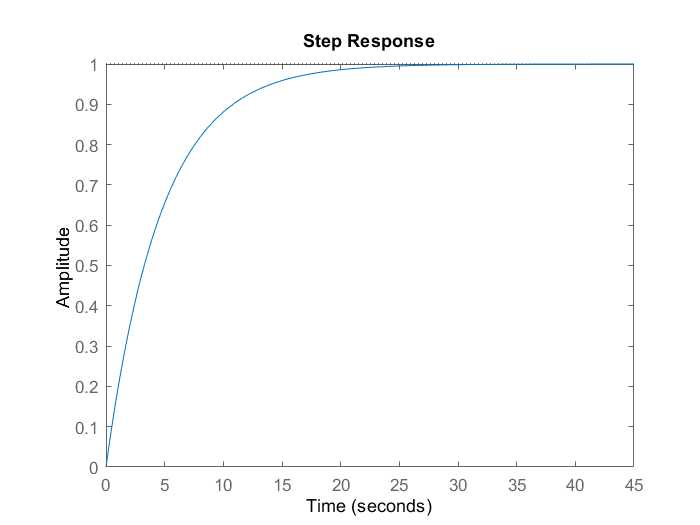

step(H)

### Real System

R = 10*1e3; % Resistencia Ideal
C = 2200*1e-6; % Capacitor Ideal

H = tf(1, [R*C 1])

H =
 
     1
  --------
  22 s + 1
 
Continuous-time transfer function.



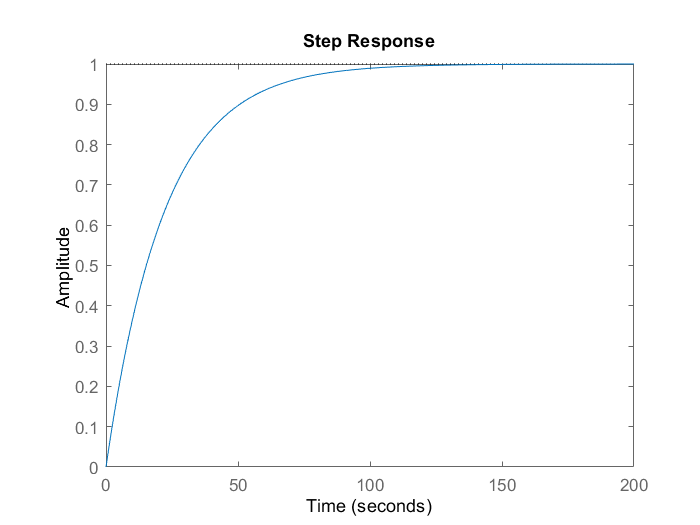

step(H)

Observamos un tiempo de establecimiento muy elevado, en el caso ideal, faltaría ver cómo se comporta en la realidad.

### Carga de data

Debemos ejecutar este código en la carpeta en la que se encuentra nuestro archivo *csv*.

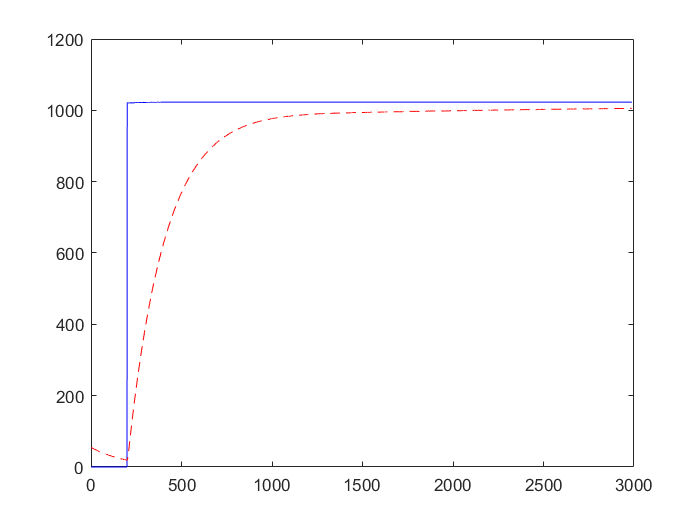

%% Cargamos la data filtrada
filename = 'filtered_data.csv';
data = readtable(filename);
data = table2array(data);

%% Asignamos variables
t = data(:, 1);
In = data(:, 2);
Out = data(:, 3);

%% Guardamos la data
save Data.mat In Out

%% Ploteo
plot(t, In, 'blue', t, Out, 'r--');

### System Identification

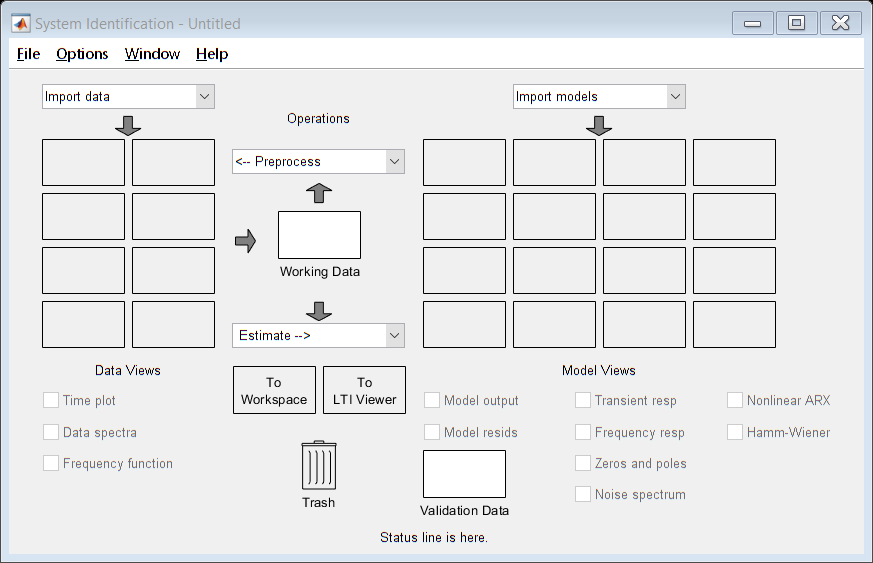

systemIdentification

save tf.mat tf1 tf2

load tf.mat
num = tf1.Numerator;
den = tf1.Denominator;

G = tf(num, den)

G =
 
    0.04692
  -----------
  s + 0.04801
 
Continuous-time transfer function.



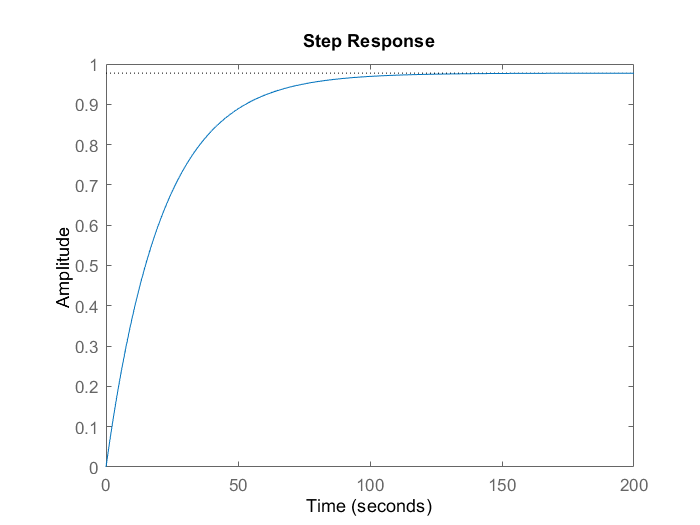


step(G)

simulink

### Discrete PID Design

%% Constants
Ts = 0.1;
P = 2.85904096042829;
I = 0.710325622775494;
D = -0.658383408043916;
N = 3.53134967167325;

%% Transfer Function
z = tf('z', Ts);

Cz = P + I*Ts/(z-1) + D*N/(1 + N*Ts/(z-1));

display(Cz)
